% Trying normalization where each factor is normalized by its
% own initial value, then dividing by 2. 

clear all

%% Parameters
tspan = 2014:0.1:2814;
numSim = 500;
hl = 0.0;
diffH = 0.1;
hu = 1.0;

peakTvsHom = tempvshomophily_fixed(numSim, tspan, hl, diffH, hu);

simulation number = 10
Elapsed time is 199.903754 seconds.
simulation number = 20
Elapsed time is 299.350360 seconds.


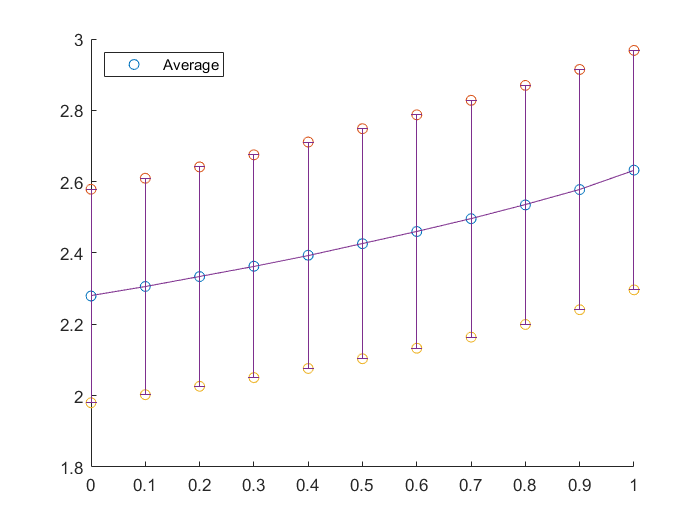

clf
avgPeakT = mean(peakTvsHom');
stdPeakT = std(peakTvsHom');
scatter(0:0.1:1, avgPeakT, 'Marker','o');
hold on
scatter(0:0.1:1, avgPeakT+stdPeakT, 'Marker', 'o');
scatter(0:0.1:1, avgPeakT-stdPeakT, 'Marker', 'o');
errorbar(0:0.1:1, avgPeakT,stdPeakT);
legend("Average", "Location","northwest")
hold off

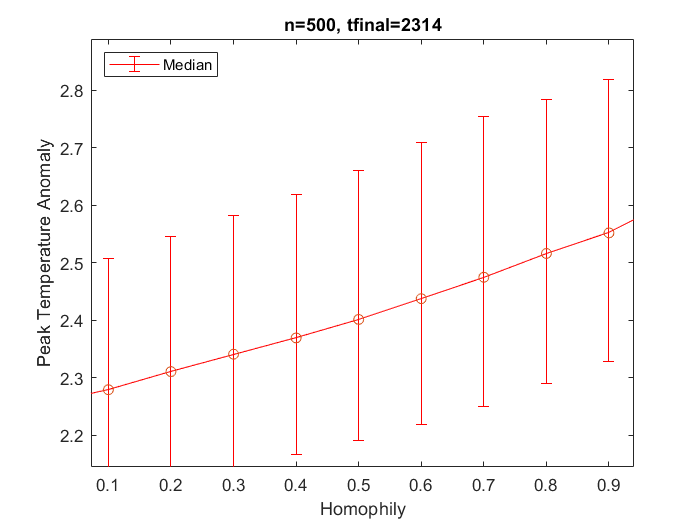

clf
medPeakT = median(peakTvsHom');
LowPeakT = quantile(peakTvsHom',0.25);
UpPeakT  = quantile(peakTvsHom',0.75);
temp_yneg = abs(medPeakT - LowPeakT);
temp_ypos = abs(medPeakT - UpPeakT);
errorbar(0:0.1:1,medPeakT, temp_yneg, temp_ypos,'Color','red')
hold on
scatter(0:0.1:1, medPeakT, 'Marker','o');

ylabel("Peak Temperature Anomaly")
xlabel("Homophily")
xlim([0,1.05])
legend("Median", "Location","northwest")
title("n=500, tfinal=2314")
hold off

1==a

Unrecognized function or variable 'a'.

peakTvsIneq = tempvsinequality(numSim, tspan)

clf
peakTvsIneq
scatter(peakTvsIneq.omega_diff, peakTvsIneq.median_,'Marker', 'o')
hold on
scatter(peakTvsIneq.omega_diff, peakTvsIneq.IQupp,  'Marker', 'o')
scatter(peakTvsIneq.omega_diff, peakTvsIneq.IQlow,  'Marker', 'o')
ylabel("Peak Temperature Anomaly")
xlabel("||I_R - I_P||")
legend("Median", "75th", "25th",'Location','northwest')
title("t_f = 10; \kappa = 0.05; \delta = 1.0; h = 0.5")

clf
peakTvsIneq
scatter(peakTvsIneq.omega_ratio, peakTvsIneq.median_,'Marker', 'o')
hold on
scatter(peakTvsIneq.omega_ratio, peakTvsIneq.IQupp,  'Marker', 'o')
scatter(peakTvsIneq.omega_ratio, peakTvsIneq.IQlow,  'Marker', 'o')
ylabel("Peak Temperature Anomaly")
xlabel("omega ratio")
legend("Median", "75th", "25th",'Location','northwest')
title("t_f = 10; \kappa = 0.05; \delta = 1.0; h = 0.5")

clf
errorbar(peakTvsIneq.omega_diff,peakTvsIneq.avg_, peakTvsIneq.std_)
xlabel("||I_{R0} - I_{P0}||")
ylabel("Peak Temperature anomaly")

clf
[sorted_diff, sortIdx] = sort(peakTvsIneq.omega_ratio);
temp_yneg = abs(peakTvsIneq.med - peakTvsIneq.iq25);
temp_ypos = abs(peakTvsIneq.med - peakTvsIneq.iq75);
%errorbar(peakTvsIneq.omega_diff,peakTvsIneq.avg_, temp_yneg, temp_ypos)
errorbar(sorted_diff,peakTvsIneq.med(sortIdx), temp_yneg(sortIdx), temp_ypos(sortIdx),'Color', 'red')
xlabel("I_{P0}/I_{R0}")
ylabel("Peak Temperature Anomaly")
legend("Median", "Location", "northwest")
